## Develop MATLAB Function

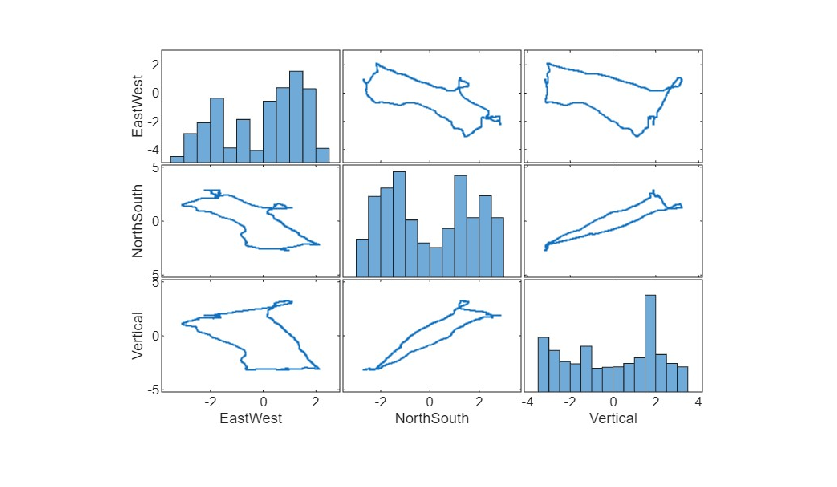

quakeData = readtable("quakeData.csv");
plotTrajectories(quakeData,200,0.098,8,15,"qt.jpg");
img = imread("qt.jpg");
figure
imshow(img);

## Package and Deploy MCP Tool

ctf = prodserver.mcp.build("plotTrajectories",wrapper="plotTrajectoriesMCP.m")

Unable to resolve the name 'prodserver.mcp.genai.mcpDescription'.

Error in prodserver.mcp.internal.defineForMCP (line 31)
                    td = prodserver.mcp.genai.mcpDescription(tools(n),fcns(n), ...
                    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in prodserver.mcp.build (line 92)
    definition = prodserver.mcp.internal.defineForMCP(opts.tool, ...
    ^^^^

endpoint = prodserver.mcp.deploy(ctf,"localhost",9910)

## Verify and Test Deployed MCP Tool

% Is the server awake?
available = prodserver.mcp.ping(endpoint)
% Does the tool exist on the server?
tf = prodserver.mcp.exist(endpoint, "plotTrajectories", "Tool")

% Construct path and URLs for input and output files.
dataFolder = string(fileparts(matlab.desktop.editor.getActiveFilename));
quakeData = "file:" + fullfile(dataFolder,"quakeData.csv");
plotFile = fullfile(dataFolder,"qTrajectories.jpg");
plotURL = "file:" + plotFile;

% Call the tool on the server using MCP protocol
[status,msg] = prodserver.mcp.call(endpoint, "plotTrajectories", quakeData, 200,0.098,8,15, ...
    plotURL)
qt = imread(plotFile);
figure
imshow(qt);